# **Detecció de presència de jugadors del Barça en la escena.**

### **1.**Seleccioneu una (o més) imatges on apareguin jugadors del Barça, que serviran de model.

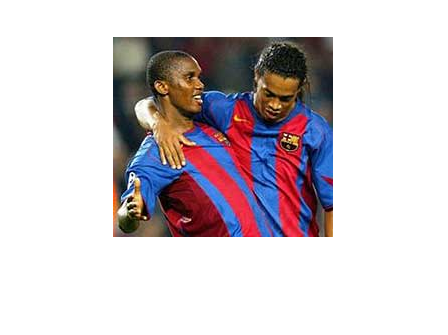

clc;
clear;
close all;

Im = imread("barcelona\28.jpg");
imshow(Im);

### Seleccioneu manualment un (o més) fragments de la imatge que continguin una part significativa de la samarreta.

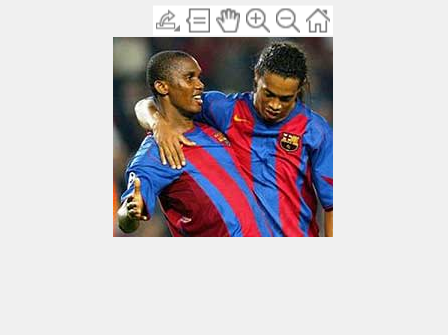

rect = getrect;

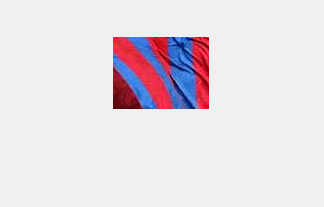

Im2 = imcrop(Im,rect);
imshow(Im2);

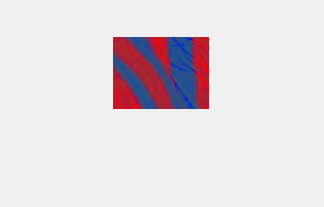

Im2 = normalitzar(Im2);
imshow(Im2);

### 2.Calculeu l’histograma de color dels fragments dels models. Aquests seran els histogrames model que usareu per buscar la samarreta en noves imatges.

hM = getHist(Im2);
%bar(hM);

### 3.Construïu histogrames de color de fragments de totes les imatges de tots els equips. Aquests fragments no poden ser seleccionats de forma manual, s'han de seleccionar de forma exhaustiva mitjançant finestra lliscant o de forma aleatòria

%Obtenim puntuacions de tots els equips
myFolder = 'barcelona';
barcelona_score=teamscore(myFolder,hM);

myFolder = 'madrid';
madrid_score=1-teamscore(myFolder,hM);

myFolder = 'acmilan';
acmilan_score=1-teamscore(myFolder,hM);

myFolder = 'chelsea';
chelsea_score=1-teamscore(myFolder,hM);

myFolder = 'juventus';
juventus_score=1-teamscore(myFolder,hM);

myFolder = 'liverpool';
liverpool_score=1-teamscore(myFolder,hM);
myFolder = 'psv';
psv_score=1-teamscore(myFolder,hM);

total_score=acmilan_score+barcelona_score+chelsea_score+juventus_score+liverpool_score;
total_score=total_score+madrid_score+psv_score;
total_score=total_score/7;

disp('acmilan score:');
disp(acmilan_score);
disp('barcelona score:');
disp(barcelona_score);
disp('chelsea score:');
disp(chelsea_score);
disp('juventus score:');
disp(juventus_score);
disp('liverpool score:');
disp(liverpool_score);
disp('madrid score:');
disp(madrid_score);
disp('psv score:');
disp(psv_score);
disp('total score:');
disp(total_score);

### 4. Compareu aquests histogrames obtinguts, amb els histogrames model

%distance Euclidean / ChiSquare

### 5. A partir dels resultats de les comparacions determinar en quines imatges apareix la samarreta del Barça

### 6. Per a fer l'histograma, useu primer l'espai RGB i després repetiu l'experiment usant l'espai HSV. Compareu els resultats

#### *Auxiliar functions*

function [distChi, score] = compareHist(hM, hC)
    distChi = chiSquare(hM,hC);
    total = distChi; %total = distChi + distEuc
    score = distChi/total; % score = distChi/total + distEu/total
end

function res = chiSquare(h1,h2)
    qi = sum(h1,'all');
    vi = sum(h2,'all');
    Q = h1./qi;
    V = h2./vi;
    N = (Q-V).^2;
    D = (Q+V);
    dist = N./D;
    res = sum(dist,'all','omitnan')/2;
end


function[Norm] = normalitzar(Im)
 R = double(Im(:,:,1));
 G = double(Im(:,:,2));
 B = double(Im(:,:,3));
 I = (R+G+B);
 r = R./I;
 g = G./I;
 b = B./I;
 Norm = imgaussfilt(cat(3,r,g,b));
 
end

function score= teamscore(myFolder,hM)
    filePattern = fullfile(myFolder, '*.jpg');
    jpegFiles = dir(filePattern);
    encerts=0;
    for k = 1:length(jpegFiles)
        baseFileName = jpegFiles(k).name;
        fullFileName = fullfile(myFolder, baseFileName);
        imageArray = imread(fullFileName);
        model = imageArray;
        model = normalitzar(model);
        hComp = {};
        bestscore=1;
        %obtenir fragments dividint imatge (FER LOOP)
        grid = 5; % TESTEJAR MILLOR MIDA
        [row, col, channels] = size(model);
        for i=0:grid-1
            for j=0:grid-1
                cell = imcrop(model, [j*col/grid i*row/grid col/grid row/grid]); 
                %cell(isnan(cell))=0;
                hC = getHist(cell); %%ARREGLAR NaN INPUTS
                %hC(isnan(hC))=0;
            
                res=chiSquare(hM,hC);
                if(bestscore>res) 
                    bestscore=res;
                end
        
                %% SELECCIONAR BEST FRAGMENTS I GUARDARLOS A hComp{}
                %%compareHist(h,hModel);
            end
        end
        if(bestscore<0.30) 
            encerts=encerts+1;    
        end
    end
    score=encerts/36;
end

function h = getHist(Im)
    R = double(Im(:,:,1));
    G = double(Im(:,:,2));
    B = double(Im(:,:,3));
    I = (R+G+B);
    R = R./I;
    G = G./I;
    B = B./I;
    hR = imhist(R,32);
    hG = imhist(G,32); % G= 1 -R - B
    hB = imhist(B,32);
    h = cat(2,hR,hB);
end